# Aeroplane roll model and lead compensator design

This livescript is a brief manual in support of the app ***aeroplane_roll_control.mlapp***.   This is a simple interface to understand the closed-loop behaviour of aeroplane roll using a lead compensator feedback design. Indeed, the main focus is on the design of the lead compensator, with the aeroplane acting as a case study.    

For more on lead compensators, see the file ***lead_design_with_bode.mlx***. 

See website for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/mainindex](https://sites.google.com/sheffield.ac.uk/controleducation/mainindex)

A group of similar files can also be downloaded through MATLAB add-ons with the toolbox name:  control101

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Engineeering context

- Open-loop behaviour

- Time constant and gain analysis

- Impact of disturbances on steady-state

- Interface and user interaction

## 1. Engineering context

A typical requirement for an aircraft is to control the bank angle. 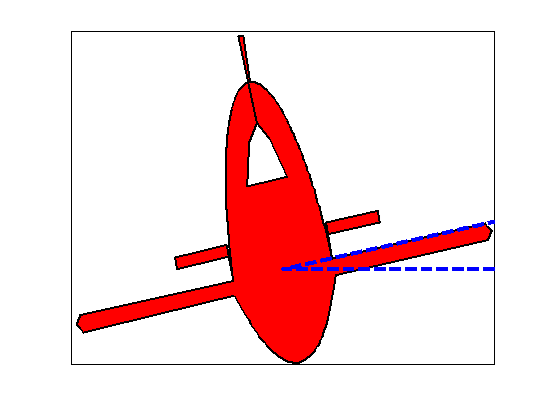

The link between the bank angle θ and the movement u of the ailerons can sometimes be approximated by models similar to the following:    


$$G\left(s\right)=\frac{C}{s^2 \left(s+a\right)};\;\;\;\;\;\;\;\;\;\;\theta \left(s\right)=G\left(s\right)u\left(s\right)$$


The open-loop system includes two integrators and thus will give zero offset to step demands, as long as it is closed-loop stable. However, a quick view of the root-loci and bode diagrams (opposite with ***C=0.01, a=0.1***) indicates that with simple proportional feedback, this system will always be closed loop unstable because there would always be 2 poles in the RHP.

G=tf(0.01,[1 0.1 0 0])

G =
 
      0.01
  -------------
  s^3 + 0.1 s^2
 
Continuous-time transfer function.
Model Properties


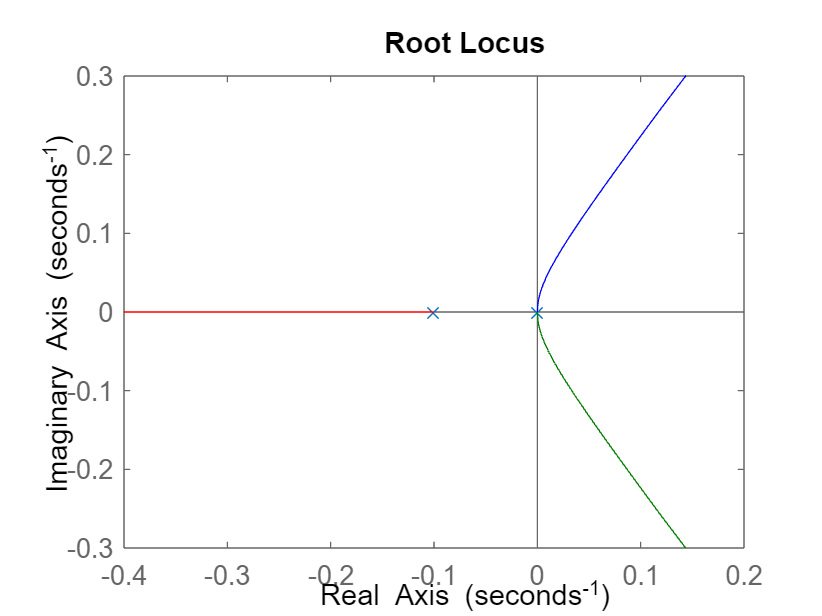

rlocus(G)

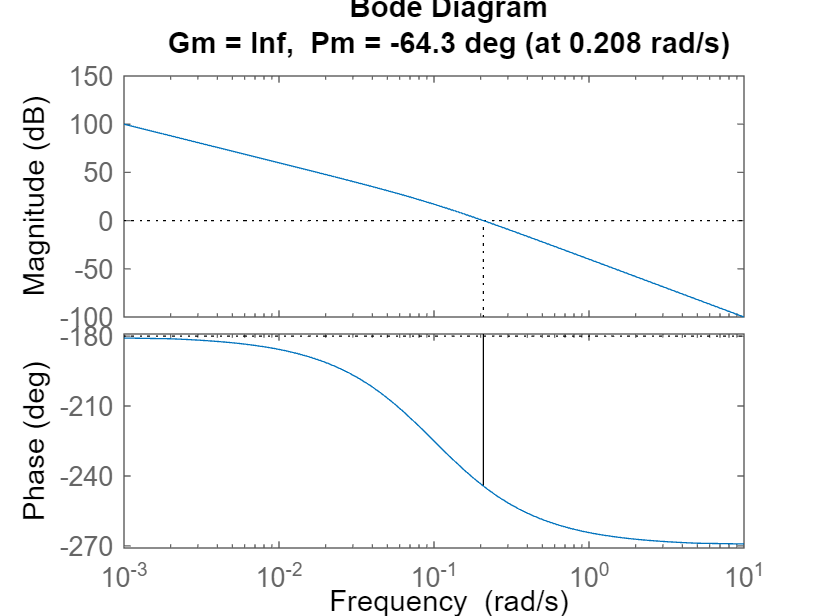

margin(G)

The phase is always below -180 degrees and thus one can not obtain a positive phase margin with proportional feedback alone. Consequently a more involved feedback design is needed.

## 2. Lead compensator design 

This script assumes the following block diagram with system G(s) and compensator M(s). Here the focus is on how to design a lead compensator assuming the specifications are  gain cross-over frequency and phase margin. There is no suggestion that single lead compensator is ideal for this scenario as the focus is more on understanding what a lead can offer in this context and how to achieve that; in fact students may conclude that an even more complex feedback design would be needed.

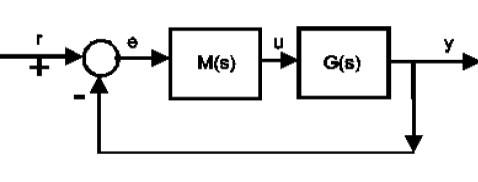

An example lead compensator, with a pole/zero ration of 4, has the following bode diagram and core attributes.

disp('Section 2 illustrations below')

Section 2 illustrations below


figure; clf
wc2=1; r=4; K=3;
zero = -wc2/sqrt(r);pole = zero*r;  
phasepeak = -atan((1/sqrt(r) - sqrt(r))/2)*180/pi;
M2=tf(K*[1 -zero],[1 -pole])

M2 =
 
  3 s + 1.5
  ---------
    s + 2
 
Continuous-time transfer function.
Model Properties


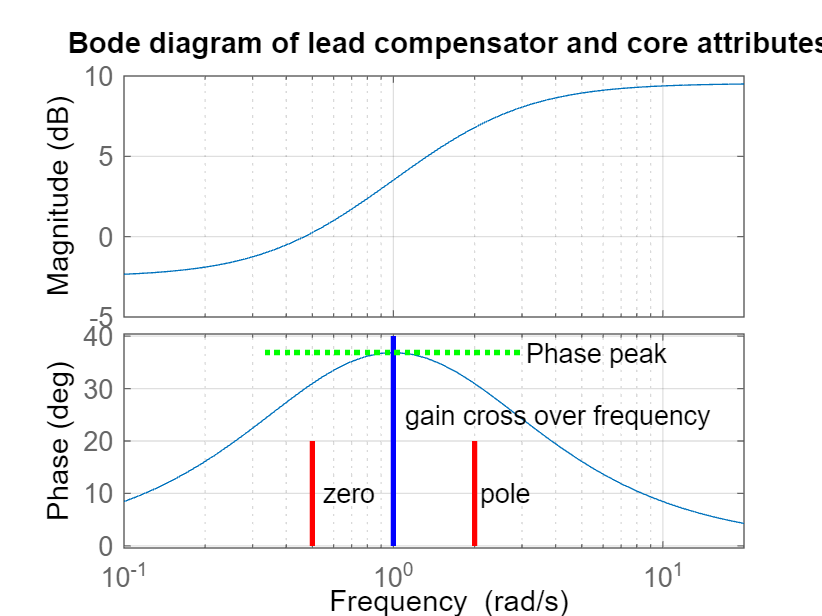

bode(M2,{wc2/10,wc2*20});grid; hold on
plot([-pole,-pole],[20,0],'r-','linewidth',2)
text(-pole*1.05,10,'pole')
plot([-zero,-zero],[20,0],'r-','linewidth',2)
text(-zero*1.1,10,'zero')
plot([wc2,wc2],[40,0],'b-','linewidth',2)
text(wc2*1.1,25,'gain cross over frequency')
plot([wc2/3,wc2*3],phasepeak*[1,1],'g:','linewidth',2)
text(wc2*3.1,phasepeak,'Phase peak')
title('Bode diagram of lead compensator and core attributes')

A core point is the positive phase characteristic which can be used to move the phase plot of the aeroplane model above -180 degrees, and thus to achieve a positive phase margin. Given the maximum phase rotation available from a lead is about 55 degrees (with a pole/zero ratio of 10), one needs to deploy this phase rotation in frequencies where the aeroplane model has a phase above about -200 degrees, or the achievable phase margin would be too small. Consequently, for simplicity, we could target the desired bandwidth or cross over frequency as where the open-loop Bode plot for the aeroplane is about -200 degrees.

Similarly, it is likely one will need a lot of phase rotation, so aim for ratio of pole to zero close to 10. Of course students can explore lower ratios to improve their general understanding of lead design.

For more detailed explanation of the design principles, please  see the file ***lead_design_with_bode.mlx***. This file will assume you are familiar with a typical design and utilise it. The full compensator structure using a mechanistic design reduces to:


$$M\left(s\right)$$

$$=K\left(\frac{s+\frac{w_c }{\sqrt{r}}}{s+w_c \sqrt{r}}\right)$$


where the given criteria are desired phase margin $\phi$ and desired bandwidth (gain cross over frequency) $w_c$. Also we exploit three formulae: 

- 
$$\theta =-\arg \left(G\left(jw_c \right)\right)-180+\phi$$


- 
$$r=\frac{\sin \left(\theta \right)+1}{1-\sin \left(\theta \right)}$$


- 
$$\;K=\frac{\sqrt{r}}{\left|G\left(jw_c \right)\right|}$$


The app here allows the users to explore the choices of *K, r* and $w_c$ more freely so they are not restricted to this design.

**Remark**: A text box in the app will give these control parameters using the current lead frequency as the start point alongside a target PM of 30 degrees. These objectives may not always be achievable!

**Remark**: Hereafter, we need to distinguish between the frequency $w$ used in *M(s)* and the actual or achieved gain cross-over frequency $w_c$, as these are different when the parameters of M(s) are chosen by some other means. So hereafter, within the app, we use and users can define *K, r* and $w$:

$M\left(s\right)$$=K\left(\frac{s+\frac{w}{\sqrt{r}}}{s+w\sqrt{r}}\right)$                        (2.1)

## 3. Numerical illustration

Using the Bode diagram and model in section 1 above, one can see that $\arg \left(G\left(jw_c \right)\right)\approx -200$ when  $w=0\ldotp 05$, that is approximately $w=\frac{a}{2}$. Here use r=6 in eqn.(2.1) for illustration (rather than the mechanistic choices for *r* defined in section 2), then:


$$M\left(s\right)$$

$$=\frac{\sqrt{6}}{\left|G\left(\textrm{j0}\ldotp 05\right)\right|}\left(\frac{s+\frac{0\ldotp 05}{\sqrt{6}}}{s+0\ldotp 05\sqrt{6}}\right)$$


Overlaying the compensated and uncompensated Bode diagrams gives the following. It is noted that this design still ensures that $w$ is the gain cross-over frequency for the compensated system due to our choice of *K*.

disp('*****************************************')
disp('Section 3 below')
G=tf(0.01,[1 0.1 0 0]);
w=0.05; r=6;
[gainGwc] = bode(G,w);
sr=sqrt(r);
K= sr/gainGwc;
zero = w/sr;
pole = w*sr;
disp('Compensator');

*****************************************


M = K*tf([1,zero],[1,pole])

Section 3 below



figure; clf
bode(G, G*M,{wc/10,w*10});grid; hold on

plot([pole,pole],[-180,-150],'r-','linewidth',2)
text(pole*1.05,-170,'pole')
plot([zero,zero],[-180,-150],'r-','linewidth',2)
text(zero*1.1,-170,'zero')

Final compensator


plot([w,w],[-180,-90],'b-','linewidth',2)
text(w,-200,'w')
legend('G','GM','Location','southwest')
title('Overlay of original and compensated system Bode diagrams')


The closed-loop step response behaviour is illustrated here alongside the resulting margins. One could conjecture from the Bode diagram that a slightly better phase margin could be achieved with a small decrease in gain *K; *clearly this would also slow down the behaviour. Users can explore this with the app.

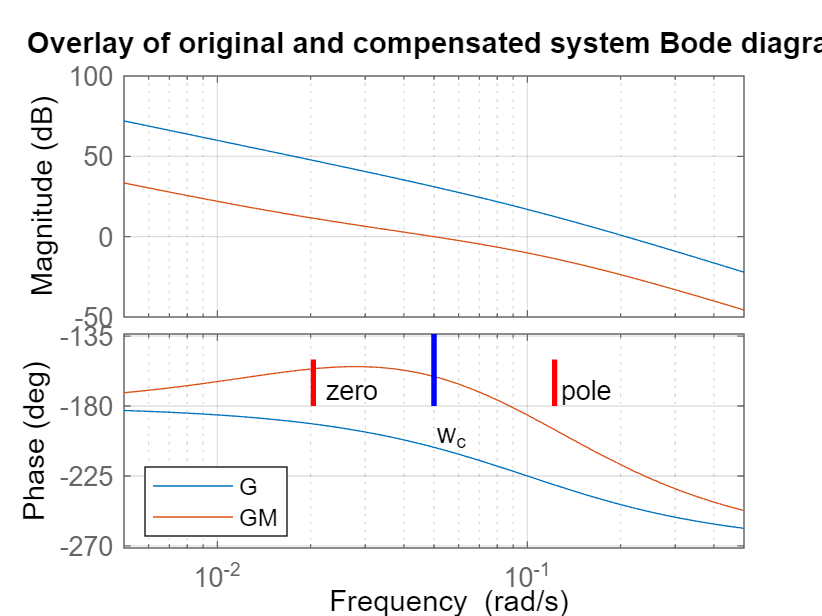

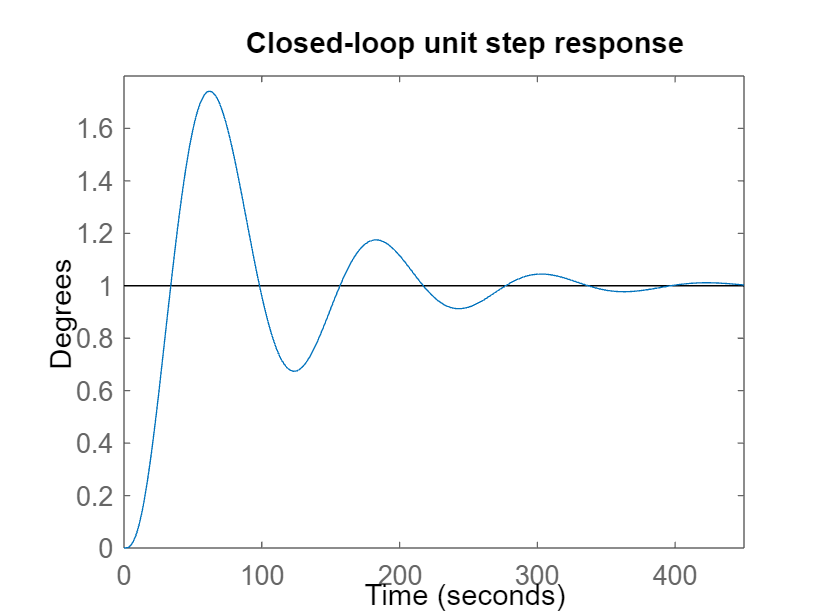

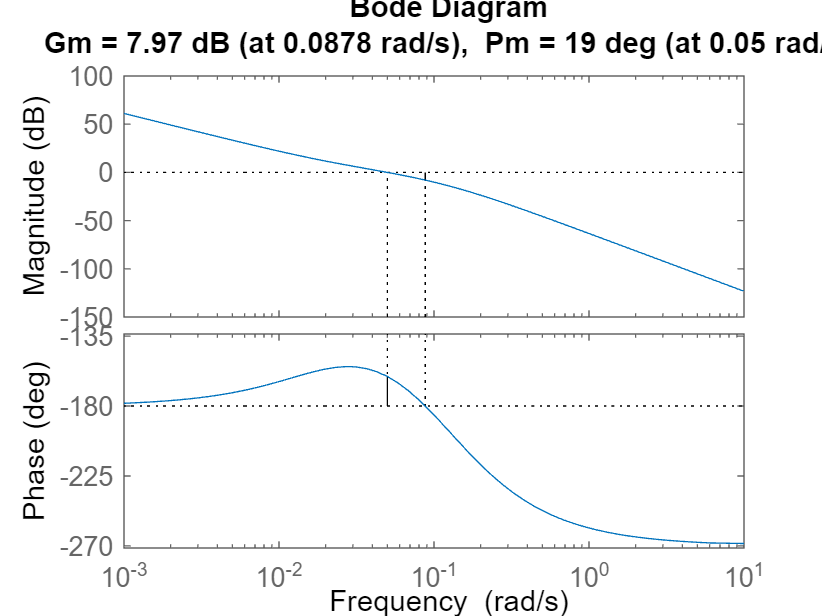

figure
step(feedback(G*M,1))
title('Closed-loop unit step response')
ylabel('Degrees')
figure
margin(G*M)

## 4. Comments

In general terms, students would be encouraged to explore different choices of the lead parameters *K, r* and $w_c$ and  the impact on bandwidth, PM and behaviour. Users can of course also use mechanical designs such as that given in section 2 where they have the relevant specified criteria.

- What happens if the controller gain is changed? How does this impact on PM, oscillation and convergence?

- What happens if the pole/zero ratio is changed?

- What happens if the frequency $w_c$ is changed?

**Remark**: The acheivable phase margin, with a sensible bandwidth, will be around 35 degrees at most. Similarly, depending on the choice of parameter *a*, one will note that a sensible bandwidth is likely to be in the region of *a/2* to *a/3 *so it does not make sense to target anything too different from this.

**Remark**: For information, the app will display values associated to a mechanistic design based on the current $w$ and a target PM of 30 degrees so users can enter these numbers should they so desire. Users will notice that if $w$ is chosen poorly (for example where the phase is less than -200 degrees), the required gain and pole/zero ratio may not be implementable. The app will show the actual gain cross-over frequency so students can explore how their choices for *K* and *r* impact on design efficacy.

## 5. Interface and user interaction

The image shows a an aircraft and a target roll angle. During the animation the plane will be seen to roll.  The animation runs for about 10 seconds to show the responses in the current scenario; this includes animation of the line plots.

The user can change  a few parameters.

- The aircraft parameters *C* and *a*. 

- The lead compensator parameters: *K, r* and w.

The bode diagram updates immediately when parameters are changed to allow the user to undertake careful design. However the animation of behaviour only activates on request through the animation button.

The simulations will be overlaid so users can compare behaviour with different compensator designs.

You can turn off the animation to give quicker simulation results using the 'animation on/animation off' button.